# Load Cell Parsing

## Import Data

clear; clc; close all;

TYPE = 0; % 0 for static, 1 for dynamic
RUNG = 3;
TRIAL = 1;

% Combine them into a single string for the switch
combination = sprintf('Y%d_R%d_T%d',TYPE, RUNG, TRIAL);

switch combination
    case 'Y1_R0_T0'
        confirmation_array = [2 3 5 7 8]; % for test data
        filename = 'load_cell_test_data.csv';
        cal_domain = 1:100;

    % Rung 1

    case 'Y0_R1_T1'
        confirmation_array = []; %n1 trial 1
        filename = 'static_rung1_trial1.csv';
        cal_domain = 35e3:44e3;
        strict_cal_domain = 36e3:41.5e3;
        zero_domain = 1:4e3;

    case 'Y1_R1_T1'
        confirmation_array = [1:7 9:12]; %n1 trial 1
        filename = 'manual_n1_trial1.csv';
        cal_domain = 1:10000;
        strict_cal_domain = 6e3:8.5e3;

    case 'Y1_R1_T2'
        confirmation_array = [1 2 4:11]; %n1 trial 1
        filename = 'manual_rung1_trial2.csv';
        cal_domain = 1:10e3;
        strict_cal_domain = 5e3:7e3;

    % Rung 2

    case 'Y0_R2_T1'
        confirmation_array = []; %n1 trial 1
        filename = 'static_rung2_trial1.csv';
        cal_domain = 1:20e3;
        strict_cal_domain = 10e3:15e3;

    case 'Y0_R2_T2'
        confirmation_array = []; %n1 trial 1
        filename = 'static_rung2_trial2.csv';
        cal_domain = 1:10e3;
        strict_cal_domain = 5e3:8e3;

    case 'Y0_R2_T3'
        confirmation_array = []; %n1 trial 1
        filename = 'static_rung2_trial3.csv';
        cal_domain = 1:10e3;
        strict_cal_domain = 5e3:7.5e3;
        
    case 'Y1_R2_T1'
        confirmation_array = 1; % for n2 trial 1
        filename = 'manual_n2_trial1.csv';
        cal_domain = 2000:12000;
        
    case 'Y1_R2_T2'
        confirmation_array = [2 3 4 5]; % for n2 trial 2
        filename = 'manual_n2_trial2.csv';
        cal_domain = 2000:8000;
        strict_cal_domain = 4e3:7e3;
    
    case 'Y1_R2_T3'
        confirmation_array = 1:10; % for n2 trial 3
        filename = 'manual_n2_trial3.csv';
        cal_domain = 2000:12000;

    case 'Y1_R2_T4'
        confirmation_array = 1:10; % for n2 trial 2
        filename = 'manual_rung2_trial4.csv';
        cal_domain = 1:10e3;
        strict_cal_domain = 6e3:8e3;

    % Rung 3

    case 'Y0_R3_T1'
        confirmation_array = []; %n1 trial 1
        filename = 'static_rung3_trial1.csv';
        cal_domain = 1:12e3;
        strict_cal_domain = 5e3:7.5e3;

    case 'Y1_R3_T1'
        confirmation_array = 6; % for n3 trial 1
        filename = 'manual_n3_trial1.csv';
        cal_domain = 2000:12000;

    case 'Y1_R3_T2'
        confirmation_array = [1 2 3 4 5 6 7 8 9]; % for n3 trial 2
        filename = 'manual_n3_trial2.csv';
        cal_domain = 2000:12000;

    case 'Y1_R3_T3'
        confirmation_array = [1 2 3 4 5 6 7 8]; % for n3 trial 3
        filename = 'manual_n3_trial3.csv';
        cal_domain = 4000:13000;

    case 'Y1_R3_T4'
        confirmation_array = [1 2 3 4 5 6 7 8 9 10]; % for n3 trial 4
        filename = 'manual_n3_trial4.csv';
        cal_domain = 2000:12000;
        strict_cal_domain = 5e3:7e3;
        
    otherwise
        fprintf('Combination %s not recognized.\n', combination);
end
opts = detectImportOptions(filename);
data = readtable(filename, opts);

## Format Data

cal_force = 0.2.*9.81;
raw_time = data.Timestamp; % e.g., 13025702930
force_data = data.Fz;   % The load cell reading
time = (raw_time - raw_time(1)) ./ 1e6;
force = -1.*force_data;
%force = force - mean(force(zero_domain));
if exist('zero_domain', 'var')
    force = force - mean(force(zero_domain));
else
    force = force - mode(force);
end

[~, uniqueIdx] = unique(time, 'stable');

% re-indexing the table to keep only unique rows
time = time(uniqueIdx, :);
force = force(uniqueIdx, :);

## Search for Peaks

minHeight = 5; %Newtons
nominal_sample_fq = 1000; % 1,000 Hz
minPeakDistance = 1.*nominal_sample_fq; % seconds
[pks, locs] = findpeaks(force, 'MinPeakHeight', minHeight, 'MinPeakDistance', minPeakDistance);

peak_times = time(locs);

%confirmation_array = 1:length(pks); %default
confirmed_peaks = pks(confirmation_array);
confirmed_peak_times = peak_times(confirmation_array);

% Display peaks
fprintf('Found %d peaks in the dataset.\n', length(confirmed_peaks));

Found 0 peaks in the dataset.


confirmed_peak_table = table(confirmed_peak_times, confirmed_peaks, 'VariableNames', {'Time_s', 'Force_Value'});
disp(confirmed_peak_table);

    Time_s    Force_Value
    ______    ___________




avg_peak = mean(confirmed_peaks)

avg_peak = NaN

measured_cal_force = mean(force(strict_cal_domain))

measured_cal_force = 1.6306

compensation_coeff = cal_force./measured_cal_force

compensation_coeff = 1.2033

avg_compensated_peak = compensation_coeff.*avg_peak

avg_compensated_peak = NaN

## Check Sampling Rate

instant_period = ones(length(time) - 1,1);
for i = 1:length(time) - 1
    instant_period(i) = time(i+1) - time(i);
end
instant_fq = 1./instant_period;

### Sampling Statistics:

smoothed_fq = instant_fq(instant_fq < 2000);
avg_fq = mean(smoothed_fq)

avg_fq = 997.6041

stdev_fq = std(smoothed_fq)

stdev_fq = 197.4571

## Graph Peaks

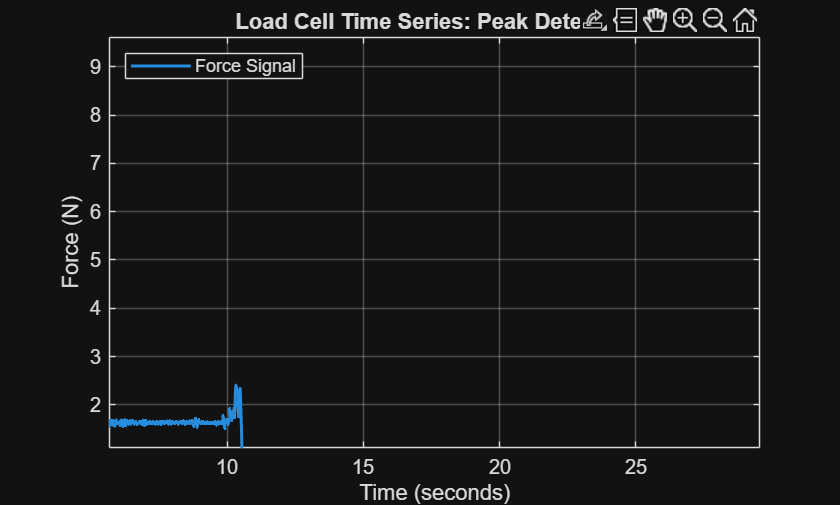

fig(1) = figure;
plot(time, force, 'LineWidth', 1.5);
hold on;
plot(peak_times, pks, 'rv', 'MarkerFaceColor', 'r'); % Red triangles at peaks
plot(confirmed_peak_times, confirmed_peaks + 0.5, 'gv', 'MarkerFaceColor', 'g'); % Red triangles at peaks
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-2 max(force)+8]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Detected Peaks', 'Confirmed Peaks', 'Location', 'northwest');

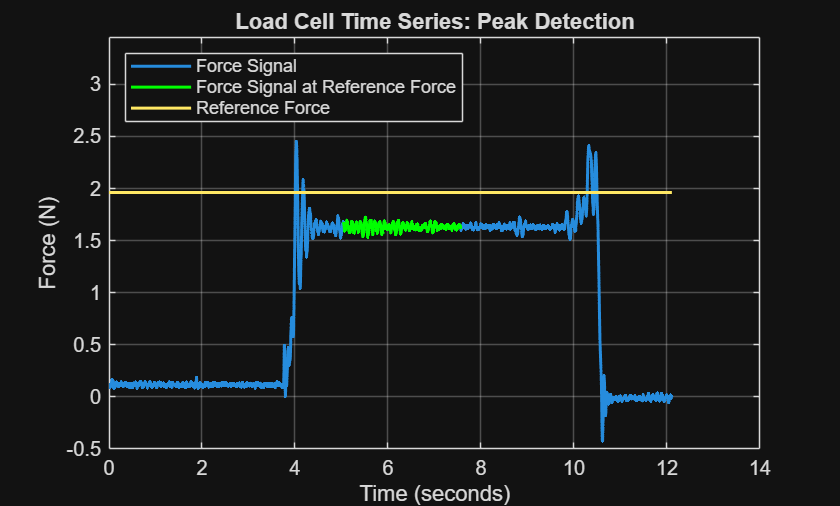

fig(6) = figure;
plot(time(cal_domain), force(cal_domain), 'LineWidth', 1.5);
hold on;
plot(time(strict_cal_domain), force(strict_cal_domain), 'g', 'LineWidth', 1.5)
plot(time(cal_domain), cal_force.*ones(1,length(cal_domain)), 'LineWidth', 1.5);
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-0.5 max(force(cal_domain))+1]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Force Signal at Reference Force', 'Reference Force', ...
    'Location', 'northwest');

## Graph Frequency Histogram

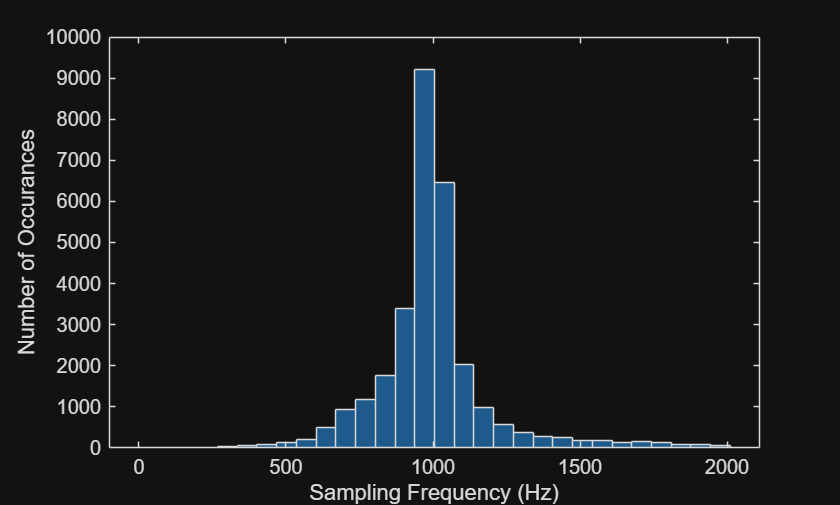

freq_label = "Sampling Frequency (Hz)";
occur_label = "Number of Occurances";
% fig(2) = figure;
% histogram(instant_fq, 30);
% xlabel(freq_label);
% ylabel(occur_label);
% fig(3) = figure;
% fq_low_pass = instant_fq(instant_fq < 20000);
% histogram(fq_low_pass, 30);
% xlabel(freq_label);
% ylabel(occur_label);
% fig(4) = figure;
% fq_lower_pass = instant_fq(instant_fq < 4000);
% histogram(fq_lower_pass, 30);
% xlabel(freq_label);
% ylabel(occur_label);
fig(5) = figure;
fq_lowest_pass = instant_fq(instant_fq < 2000);
histogram(fq_lowest_pass, 30);
xlabel(freq_label);
ylabel(occur_label);